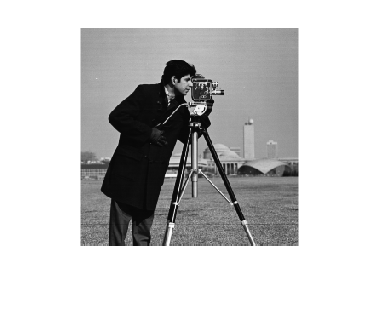

clear
cm=imread('cameraman.tif');
[n,m]=size(cm);
imshow(cm)

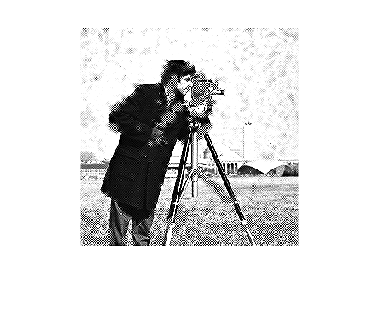


cm=fftshift(cm);  %中心变换
cf=fft2(cm);     %2维快速傅里叶变换
u=[-floor(m/2):floor((m-1)/2)];  %水平频率
v=[-floor(n/2):floor((n-1)/2)];  %垂直频率
[uu,vv]=meshgrid(u,v);  %频域平面上的网格节点
b1=1./(1+(sqrt(uu.^2+vv.^2)/15).^2);   %构造一阶巴特沃滋低通滤波器(截止频率d0=15)
cf1=b1.*cf;  %低通滤波
cm1=real(ifft2(cf1));  %傅里叶逆变换，取复数的实部
cm1=ifftshift(cm1);   %中心还原
cml=uint8(cm1);
imshow(cm1)